# Support Vector Machines

This question uses a subset of the iris data - only the sepal widths and sepal lengths for the versicolor and virginica classes:

clear all;
load('binary.mat', 'examples', 'labels');

Use the whole dataset (without splitting) to train a standard Support Vector Machine (SVM) and visualise its linear decision boundary. Note that the dataset has already been z-score standardised.

Marks are available for:

- An appropriate call to train an SVM on the whole dataset using default hyperparameters [2 marks]

- Generating a "grid" of testing data which spans the minimum and maximum value of each feature in the training dataset [8 marks]

- Using your trained SVM to classify the testing data you have generated [2 marks]

- Generating a scatter plot of your testing data, with each point colour-coded by the associated classification result [2 marks]

- Superimposing the original training data so that it is clearly visible [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

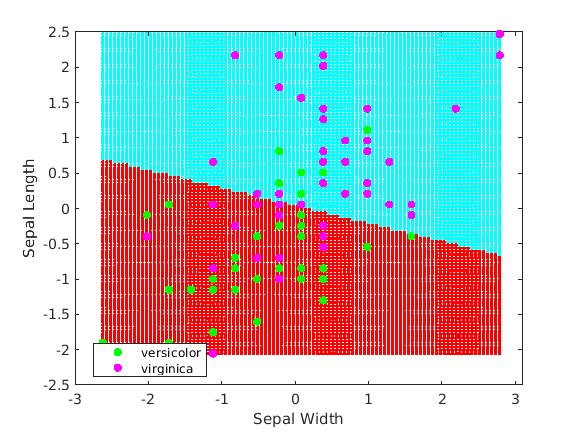

% add as many lines of code as you need below:
m = fitcsvm(examples, labels); %call to train an SVM on the whole dataset using default hyperparameters

x_min = min(examples{:,1});
x_max = max(examples{:,1});
x_jump = (x_max - x_min) / 100; %find the max, min and jump values for the first feature

y_min = min(examples{:,2});
y_max = max(examples{:,2});
y_jump = (y_max - y_min) / 100; %find the max, min and jump values for the second feature


xs = [];
ys = [];
xys = [];

for x = x_min:x_jump:x_max %loop for each possible x value
    for y = y_min:y_jump:y_max %loop for each possible x value
        %record the current coordinate
        xs(end+1,1) = x; 
        ys(end+1,1) = y;
        
        %xys(end+1, :) = [x,y]
        
        %xs = [xs; x];
        %ys = [ys; y]; 
    end
end

predictions = predict(m, [xs ys]); %generate a prediction using previously trained model , give all possible x and y values found as parameters

gscatter(xs, ys, predictions) %plot prediction
xlabel('Sepal Width')
ylabel('Sepal Length')

hold on
gscatter(examples{:,1}, examples{:,2}, labels, 'gm') %plot original example values